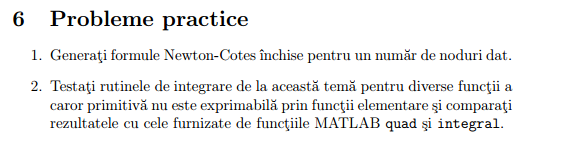

## Test Integration Routines on Challenging Functions

% Define functions without elementary antiderivatives
f1 = @(x) exp(-x.^2);                 % Gaussian function
f2 = @(x) sin(x.^2);                  % Fresnel-type
f3 = @(x) log(1 + x.^2);              % Smooth, no closed-form primitive
a = 0;
b = 1;
tol = 1e-6;

## Custom: Adaptive Simpson

I1 = adaptquad_simp(f1, a, b, tol);
I2 = adaptquad_simp(f2, a, b, tol);
I3 = adaptquad_simp(f3, a, b, tol);

## Custom: Newton-Cotes n = 4

[w, x_nodes] = newton_cotes_closed(4, a, b);
I1_nc = sum(w .* arrayfun(f1, x_nodes));
I2_nc = sum(w .* arrayfun(f2, x_nodes));
I3_nc = sum(w .* arrayfun(f3, x_nodes));

## Built-in MATLAB integrators

I1_integral = integral(f1, a, b);
I2_integral = integral(f2, a, b);
I3_integral = integral(f3, a, b);

I1_quad = quad(f1, a, b);
I2_quad = quad(f2, a, b);
I3_quad = quad(f3, a, b);

## Results

fprintf('\nFunction: exp(-x^2)\n');


Function: exp(-x^2)


fprintf('Adaptive Simpson: %.8f\n', I1);

Adaptive Simpson: 0.74682413


fprintf('Newton-Cotes (n=4): %.8f\n', I1_nc);

Newton-Cotes (n=4): 0.74683371


fprintf('integral: %.8f\n', I1_integral);

integral: 0.74682413


fprintf('quad:     %.8f\n', I1_quad);

quad:     0.74682418



fprintf('\nFunction: sin(x^2)\n');


Function: sin(x^2)


fprintf('Adaptive Simpson: %.8f\n', I2);

Adaptive Simpson: 0.31026830


fprintf('Newton-Cotes (n=4): %.8f\n', I2_nc);

Newton-Cotes (n=4): 0.31026142


fprintf('integral: %.8f\n', I2_integral);

integral: 0.31026830


fprintf('quad:     %.8f\n', I2_quad);

quad:     0.31026832



fprintf('\nFunction: log(1 + x^2)\n');


Function: log(1 + x^2)


fprintf('Adaptive Simpson: %.8f\n', I3);

Adaptive Simpson: 0.26394350


fprintf('Newton-Cotes (n=4): %.8f\n', I3_nc);

Newton-Cotes (n=4): 0.26389920


fprintf('integral: %.8f\n', I3_integral);

integral: 0.26394351


fprintf('quad:     %.8f\n', I3_quad);

quad:     0.26394328
